# Projective and variational methods

## Taks 1

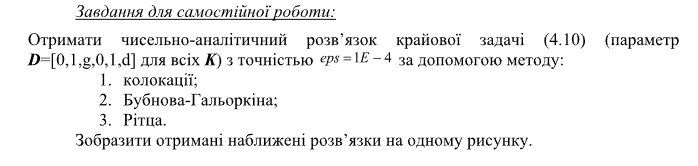

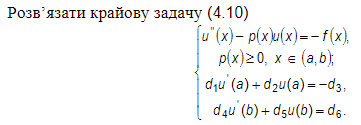

clear;

% код взяв з відповідного заняття
% підправив деякі моменти та додав коментарі
% до ключових етапів (описату саму ідею метода)

a = -1; b = 1;
D = [0, 1, 1, 0, 1, 17];
eps = 10^(-4);

p = @(x)(acos(x));
f = @(x)(1 + x .* sin(1 + x^2));

**Основна ідея мет.кол. - переводимо BVP в еквівалентну алгебр.сист та вирішуємо вже її**

**Як відбувається ця побудова алгебраїчної системи: **

Для кожної точки x(j) у цьому дискретизованому просторі код будує алгебраїчну систему, представлену матрицею коефіцієнтів A та вектором B. 

Ця система виводиться з вихідного диференціального рівняння та умов колокації  (які в даному випадку, здається, представлені функціями pfun(xj) та ffun(xj)).

Далі просто вирішуємо через A \ B. Та записуємо шуканий поліном.

$$P = \frac{1894153979357407\,x^{5}}{144115188075855872}-\frac{1843185812447727\,x^{4}}{9007199254740992}+\frac{4566578196953605\,x^{3}}{18014398509481984}-\frac{2275664880160357\,x^{2}}{4503599627370496}+\frac{1625005138165349\,x}{1125899906842624}$$

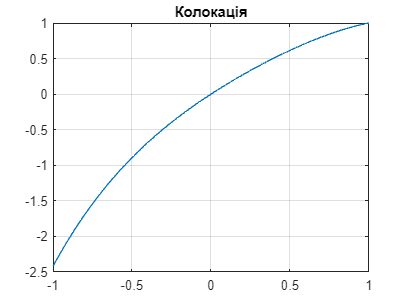

run(@mm_coloc, "Колокація", p, f, a, b, D, eps);

Ідея методу Галеркіна полягає у виборі набору базисних функцій, якими може бути будь-який набір лінійно незалежних функцій, що охоплюють простір потенційних розв'язків. Наближений розв'язок диференціального рівняння виражається у вигляді лінійної комбінації цих базисних функцій.

Коефіцієнти лінійної комбінації вибираються таким чином, щоб залишок (різниця між лівою і правою частинами диференціального рівняння, оцінена при наближеному розв'язку) був ортогональним до кожної з базисних функцій. Все це робиться з єдиною метою - отримати можливість розв. проблему чисельно

$$P = -\frac{6293335226415241\,x^{4}}{36028797018963968}+\frac{4135656985505749\,x^{3}}{18014398509481984}-\frac{560000733986227\,x^{2}}{1125899906842624}+\frac{812044402530109\,x}{562949953421312}$$

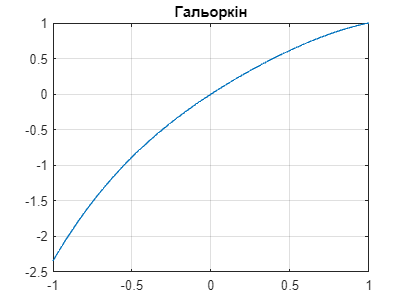

run(@mm_galer, "Гальоркін", p, f, a, b, D, eps);

Як і метод Гальоркіна, метод Рітца також представляє розв'язок як лінійну комбінацію базисних функцій. Однак коефіцієнти в цій комбінації підбираються так, щоб мінімізувати наш лінійний оператор (наш $\Phi$ в описі (книга)). 

$$P = -\frac{6293335226415241\,x^{4}}{36028797018963968}+\frac{4135656985505749\,x^{3}}{18014398509481984}-\frac{560000733986227\,x^{2}}{1125899906842624}+\frac{812044402530109\,x}{562949953421312}$$

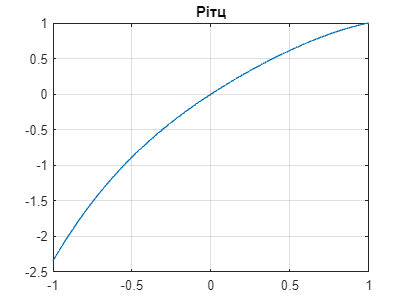

run(@mm_ritz, "Рітц", p, f, a, b, D, eps);

export("Computational methods/Lab6.mlx")

ans = 'E:\Work\Applied math\Matlab\Lab6.pdf'

function run(methodFunc, titleStr, p, f, a, b, D, eps)
    Y = methodFunc(p, f, a, b, D, eps);
    X = linspace(a, b, length(Y));

    plot(X, Y);
    title(titleStr);
    grid on;
end

function Y = mm_coloc(pfun, ffun, a, b, D, e)
    % початкові функції та ініціалізація параметрів
    f0 = [(D(2) - D(1)) ./ b, D(1)]; 
    n = 1; F = 0; Y = f0; 
    
    while ~F & n <= 15
        % Зберігаємо попередній Y
        YY = Y; 
    
        n = n + 1; 
        N = n + 2; 
    

        x = linspace(0, b, N); 
        x = x(2 : N - 1);
    
        % наша система рівнянь
        A = zeros(n, n); 
        B = zeros(n, 1); 
    
        for j = 1 : n 
            xj = x(j); 
            px = pfun(xj); 
            for i = 1 : n 
                fi = zeros(i + 2, 1); 
                fi(1) = 1; 
                fi(2) = -b; 
    
                ddf = polyder(polyder(fi)); % друга похідна
                fi = polysum(ddf, -px .* fi); 
    
                A(j, i) = polyval(fi, xj); 
    
                clear fi ddf pf 
            end 
            B(j) = -ffun(xj) + px .* polyval(f0, xj); 
        end 
    
        % Вирішення СЛР
        c = A \ B; 
        clear A B px 
    
        % Перераховуємо Y
        Y = f0; 
        for i = 1 : n 
            fi = zeros(i + 2, 1); 
            fi(1) = 1; 
            fi(2) = -b;
            fi = c(i) .* fi; 
            Y = polysum(Y, fi); 
        end 
    
        clear fi c 
    
        % Просто різниця, щоб перевірити eps
        fi = polysum(Y, -YY); 
        F = abs(polyint(0, b, fi)) <= e; 
        clear fi 
    end 
    
    % переводимо вектор в символи
    P = poly2sym(Y, sym('x'))
    nx = 201; x = linspace(a, b, nx); 
    
    % та рахуємо
    for i = 1 : nx 
        Y(i) = subs(P, x(i)); 
    end
end
    
        
function Y = mm_galer(pfun, ffun, a, b, D, e)     
    x = sym('x'); 
    f0 = [(D(2) - D(1)) ./ b, D(1)]; 
    f_0 = poly2sym(f0, x); 
    df0 = polyder(f0); n = 1; 
    F = 0; Y = f0; 
    while ~F & n <= 15 
        YY = Y; 
        n = n + 1; 
        A = zeros(n, n); 
        B = zeros(n, 1); 

        for j = 1 : n 
    
            % fj функції, той самий "розв'язок"
            fj = zeros(j+2, 1); 
            fj(1) = 1; 
            fj(2) = -b; 
    
            dfj = polyder(fj);    % похідна  
    
            for i = 1 : n 
                % 0
                fi = zeros(i+2, 1); 
                fi(1) = 1; 
                fi(2) = -b; 
    
                dfi = polyder(fi); 
    
                % 1
                z = conv(dfj, dfi); % згортка
                a1 = polyint(0, b, z); 
    
                % 2
                z = conv(fj, fi); 
                z = poly2sym(z, x) * pfun(x); 
                a2 = i_simpsym(0, b, z, 1e-10, 10000); 
    
                % 3
                A(j, i) = a1 + a2; 
    
                clear fi dfi z 
            end 
    
            % Згортка та інтегрування
            z = conv(df0, dfj); 
            a1 = polyint(0, b, z); 
    
            % Рахуємо (ffun - pfun * f_0) * fj та інтегруємо
            z = (ffun(x) - pfun(x) * f_0) * poly2sym(fj, x); 
            a2 = i_simpsym(0, b, z, 1e-10, 10000); 
    
            B(j) = a2 - a1; 
    
            clear fj dfj z 
        end
        c = A \ B;  
        clear A B 
        Y = f0; 
        for i = 1 : n 
            fi = zeros(i+2, 1); 
            fi(1) = 1; fi(2) = -b;
            fi=c(i) .* fi;
            Y = polysum(Y, fi); 
        end 
        clear fi c 
        fi = polysum(Y, -YY); 
        F = abs(polyint(0, b, fi)) <= e; 
        clear fi 
    end 
    
    % переводимо вектор в символи
    P = poly2sym(Y, sym('x'))
    nx = 201; x = linspace(a, b, nx); 
    
    % та рахуємо
    for i = 1 : nx 
        Y(i) = subs(P, x(i)); 
    end
end




function Y = mm_ritz(pfun, ffun, a, b, D, e)     
    x = sym('x'); 
    f0 = [(D(2) - D(1)) ./ b, D(1)]; 
    f_0 = poly2sym(f0, x); 
    df0 = polyder(f0); 
    n = 1; 
    F = 0; 
    Y = f0; 
    while ~F & n <= 15 
        YY = Y; 
        n = n + 1; 
        A = zeros(n, n); 
        B = zeros(n, 1); 
        for j = 1 : n 
            fj = zeros(j + 2, 1); 
            fj(1) = 1; 
            fj(2) = -b; 
            dfj = polyder(fj); 
            for i = 1 : n 
                fi = zeros(i+2, 1); 
                fi(1) = 1; 
                fi(2) = -b; 
                dfi = polyder(fi); 
                z = conv(dfj, dfi); 
                a1 = polyint(0, b, z); 
                z = conv(fj, fi); 
                z = poly2sym(z, x) * pfun(x); 
                a2 = i_simpsym(0, b, z, 1e-10, 10000); 
                A(j, i) = a1 + a2; 
                clear fi dfi z 
            end 
            z = conv(df0, dfj); 
            a1 = polyint(0, b, z); 
            z = (ffun(x) - pfun(x) * f_0) * poly2sym(fj, x); 
            a2 = i_simpsym(0, b, z, 1e-10, 10000); 
            B(j) = a2 - a1; 
            clear fj dfj z 
        end 
        c = A \ B;  
        clear A B 
        Y = f0; 
        for i = 1 : n 
            fi = zeros(i+2, 1); 
            fi(1) = 1; 
            fi(2) = -b; 
            fi = c(i) .* fi; 
            Y = polysum(Y, fi); 
        end 
        clear fi c 
        fi = polysum(Y, -YY); 
        F = abs(polyint(0, b, fi)) <= e; 
        clear fi 
    end 
    
    % переводимо вектор в символи
    P = poly2sym(Y, sym('x'))
    nx = 201; x = linspace(a, b, nx); 
    
    % та рахуємо
    for i = 1 : nx 
        Y(i) = subs(P, x(i)); 
    end
end





function S = polysum(P, Q) 
    % Знаходження S = P+Q, де P, Q  - поліноми

    % compare
    if length(P) < length(Q)
        S = polysum(Q, P);
        return;
    end

    nP = length(P); nQ = length(Q);

    % compute sum
    nS = nP; S = P; j = nS; 
    for i = nQ : -1 : 1 
        S(j) = S(j) + Q(i); j = j - 1; 
    end

    % work with "tail"
    j = 0; 
    for i = 1 : nS
        if S(i) ~= 0 
            j = 1; break; 
        end 
    end 
    if j 
        S = S(i : nS);
    end 
end




function  s = polyint(a, b, P) 
    % Знаходження визначеного інтеграла від поліному Pn(x)
    n = length(P); n2 = n + 1; 
    s = 0; 

    % just sum of p*x^{n+1}
    for i = 1 : n
        j = n2 - i; 
        s = s + P(i) ./ j .* (b .^ j - a .^ j); 
    end 
end 



function s = i_simpsym(a, b, f, e, mki) 
    % рахуємо визначенний інтеграл через Сімпсона
    % з заданою точністю + макс. згущенням

    hn = 0.5 .* (b - a); 
    S1 = subs(f, 'x', a) + subs(f, 'x', b); 
    S2 = 0; 
    t = 0.5 .* (b + a); S4 = subs(f, 'x', t); 
    s = hn .* (S1 + 4 .* S4) ./ 3; 
    k = 0; F = 0; 
    while ~F & k < mki 
        k = k + 1; ho = hn; hn = 0.5 .* hn; 
        S2 = S2 + S4; S4 = 0; t = a + hn; 
        while t < b 
            S4 = S4 + subs(f, 'x', t); t = t + ho; 
        end 
        ss = hn .* (S1 + 4 .* S4 + 2 .* S2) ./ 3; 
        F = abs(ss - s) ./ 15 < e; s = ss; 
    end 
end 